%建立符号变量a(发展系数)和b(灰作用量)
syms a b;
c = [a b]';

%原始数列 A
A = [0.05555426,-0.05396778,0.054750825,-0.002578112,-0.242598236,-0.190174382,0.39360871,0.117000036,0.082999977,0.004999961];
n = length(A);

%对原始数列 A 做累加得到数列 B
B = cumsum(A);

%对数列 B 做紧邻均值生成
for i = 2:n
    C(i) = (B(i) + B(i - 1))/2; 
end
C(1) = [];

%构造数据矩阵 
B = [-C;ones(1,n-1)];
Y = A; Y(1) = []; Y = Y';

%使用最小二乘法计算参数 a(发展系数)和b(灰作用量)
c = inv(B*B')*B*Y;
c = c';
a = c(1); b = c(2);

%预测后续数据
F = []; F(1) = A(1);
for i = 2:(n+10)
    F(i) = (A(1)-b/a)/exp(a*(i-1))+ b/a;
end

%对数列 F 累减还原,得到预测出的数据
G = []; G(1) = A(1);
for i = 2:(n+10)
    G(i) = F(i) - F(i-1); %得到预测出来的数据
end

disp('预测数据为：');

预测数据为：


G

G =     0.0556    0.0249    0.0277    0.0308    0.0343    0.0381    0.0424    0.0471    0.0524    0.0583    0.0648    0.0721    0.0802    0.0891    0.0991    0.1102    0.1226    0.1363    0.1516    0.1686



%模型检验

H = G(1:10);
%计算残差序列
epsilon = A - H;

%法一：相对残差Q检验
%计算相对误差序列
delta = abs(epsilon./A);
%计算相对误差Q
disp('相对残差Q检验：')

相对残差Q检验：


Q = mean(delta)

Q = 2.9770


%法二：方差比C检验
disp('方差比C检验：')

方差比C检验：


C = std(epsilon, 1)/std(A, 1)

C = 0.9824


%法三：小误差概率P检验
S1 = std(A, 1);
tmp = find(abs(epsilon - mean(epsilon))< 0.6745 * S1);
disp('小误差概率P检验：')

小误差概率P检验：


P = length(tmp)/n

P = 0.7000

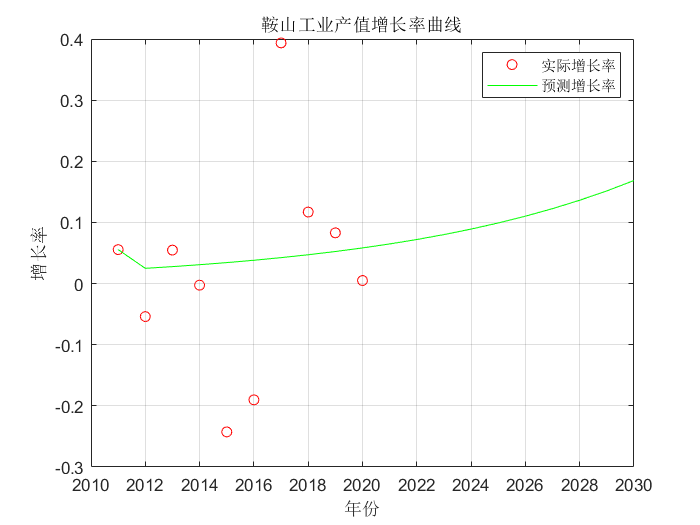


%绘制曲线图
t1 = 2011:2020;
t2 = 2011:2030;

plot(t1, A,'ro'); hold on;
plot(t2, G, 'g-');
xlabel('年份'); ylabel('增长率');
legend('实际增长率','预测增长率');
title('鞍山工业产值增长率曲线');
grid on;